# Binaural Audio

## Voice1 60º


clear all

[voice,fs_voice] = audioread('Prueba_voz.wav');
%convert stereo to mono
voice_mono = (voice(:,1)+voice(:,2))/2;

%Applying HRTF to the voice audio

[elev_voice, fs_elevevoice] = audioread("H0e060a.wav");

b_voiceL = transpose(elev_voice(:,1)); 
a_voiceL = 1;
HRTF_voiceL = filter(b_voiceL,a_voiceL, voice_mono);


b_voiceR = transpose(elev_voice(:,2)); 
a_voiceR = 1;
HRTF_voiceR = filter(b_voiceR,a_voiceR, voice_mono);

HRTF_voice = [HRTF_voiceL, HRTF_voiceR];



## Song 0º

[song,fs_song] = audioread('Song.wav');


%convert stereo to mono
song_mono = (song(:,1)+song(:,2))/2;

%Applying HRTF to the song audio

[elev_song, fs_elevsong] = audioread("H0e000a.wav");

b_songL = transpose(elev_song(:,1)); 
a_songL = 1;
HRTF_songL = filter(b_songL,a_songL, song_mono);


b_songR = transpose(elev_song(:,2)); 
a_songR = 1;
HRTF_songR = filter(b_songR,a_songR, song_mono);

HRTF_song = [HRTF_songL, HRTF_songR];




## Voice2 -90º

[voice2,fs_voice] = audioread('lolsitodxd.wav');

%convert stereo to mono
voice2_mono = (voice2(:,1)+voice2(:,2))/2;

%Applying HRTF to the voice2 audio

[elev_voice2, fs_elev] = audioread("H10e090a.wav");

b_voice2L = transpose(elev_voice2(:,1)); 
a_voice2L = 1;
HRTF_voice2L = filter(b_voice2L,a_voice2L, voice2_mono);


b_voice2R = transpose(elev_voice2(:,2)); 
a_voice2R = 1;
HRTF_voice2R = filter(b_voice2R,a_voice2R, voice2_mono);

HRTF_voice290 = [HRTF_voice2L, HRTF_voice2R];
HRTF_voice2(:,1) = HRTF_voice290(:,2);
HRTF_voice2(:,2) = HRTF_voice290(:,1);


Binaural_audio = cat(1,HRTF_voice, HRTF_voice2, HRTF_song);

sound(Binaural_audio, fs_song)


audiowrite("BinauralAudio.mp4", Binaural_audio, fs_song)

## Plots

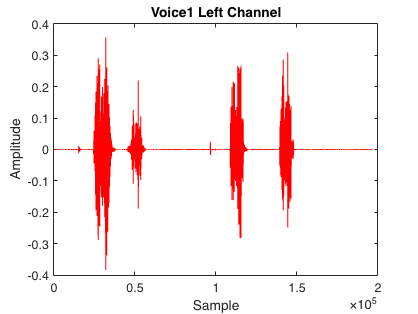

plot(HRTF_voiceL,color="R")
title("Voice1 Left Channel")
xlabel("Sample")
ylabel("Amplitude")

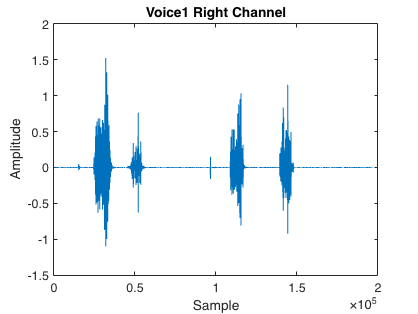


plot(HRTF_voiceR)
title("Voice1 Right Channel")
xlabel("Sample")
ylabel("Amplitude")

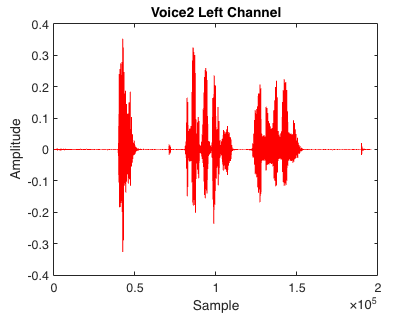




%We use HRTF2_voiceR for the leftchannel because this is for a negative
%degree
plot(HRTF_voice2R,color="R")
title("Voice2 Left Channel")
xlabel("Sample")
ylabel("Amplitude")

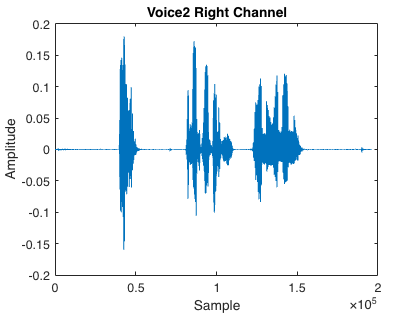



%We use HRTF2_voiceL for the rightchannel because this is for a negative
%degree
plot(HRTF_voice2L)
title("Voice2 Right Channel")
xlabel("Sample")
ylabel("Amplitude")

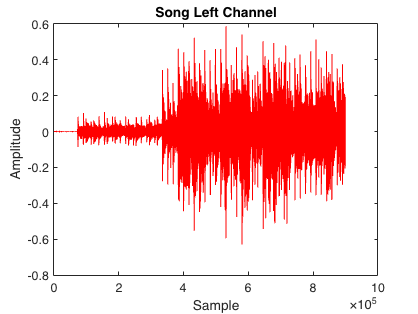


plot(HRTF_songL,color="R")
title("Song Left Channel")
xlabel("Sample")
ylabel("Amplitude")

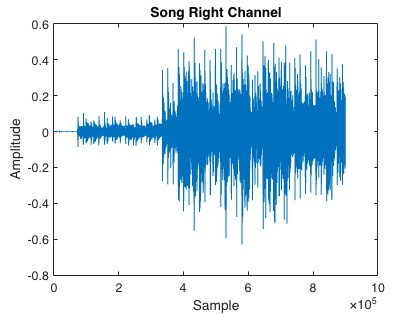


plot(HRTF_songR)
title("Song Right Channel")
xlabel("Sample")
ylabel("Amplitude")

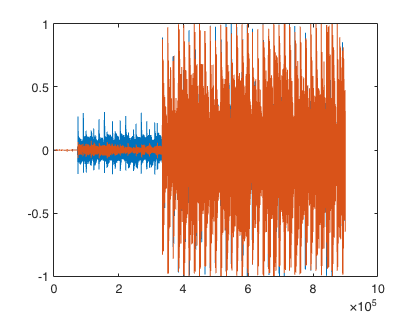


plot(song)